## How do you design a car to ensure a smooth ride?

Many parts of a vehicle contribute to ensuring a smooth ride for passengers. The suspension system contains key components: tires, shock absorbers, and linkages. Together, these cushion the vehicle's response to bumps and dips in the road. 

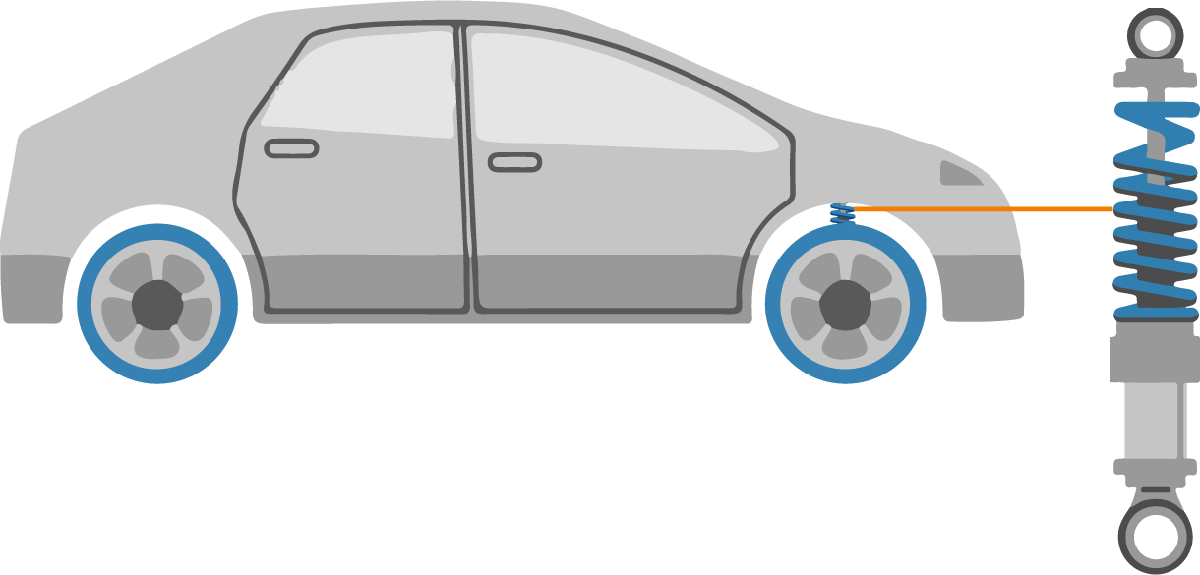

*A shock absorber helps to provide a smooth ride and reduces wear on vehicle components*

Shock absorbers use hydraulic fluid to dissipate mechanical energy, reducing the vehicle's response to a shock. How can you choose the right shock damping to smooth out the ride while preserving vehicle control? The answer lies in dynamic modeling. In this live script, you will

- examine the mass-spring-damper model,

- solve for its solutions in Simulink, and

- apply it to tune the damping of a suspension system to meet design requirements.

 **Pro-tip**: If you've never used Simulink before, consider working through [Simulink onramp](https://matlabacademy.mathworks.com/details/simulink-onramp/simulink): a free three-hour introductory course for Simulink.

# The Mass-Spring-Damper

## 1. The mass-spring-damper model

The mass-spring-damper model is a simple idealization that can be applied to a wide variety of vibrating physical systems. As the name suggests, the mass-spring-damper system contains three idealized components: a mass, a spring, and a damper.

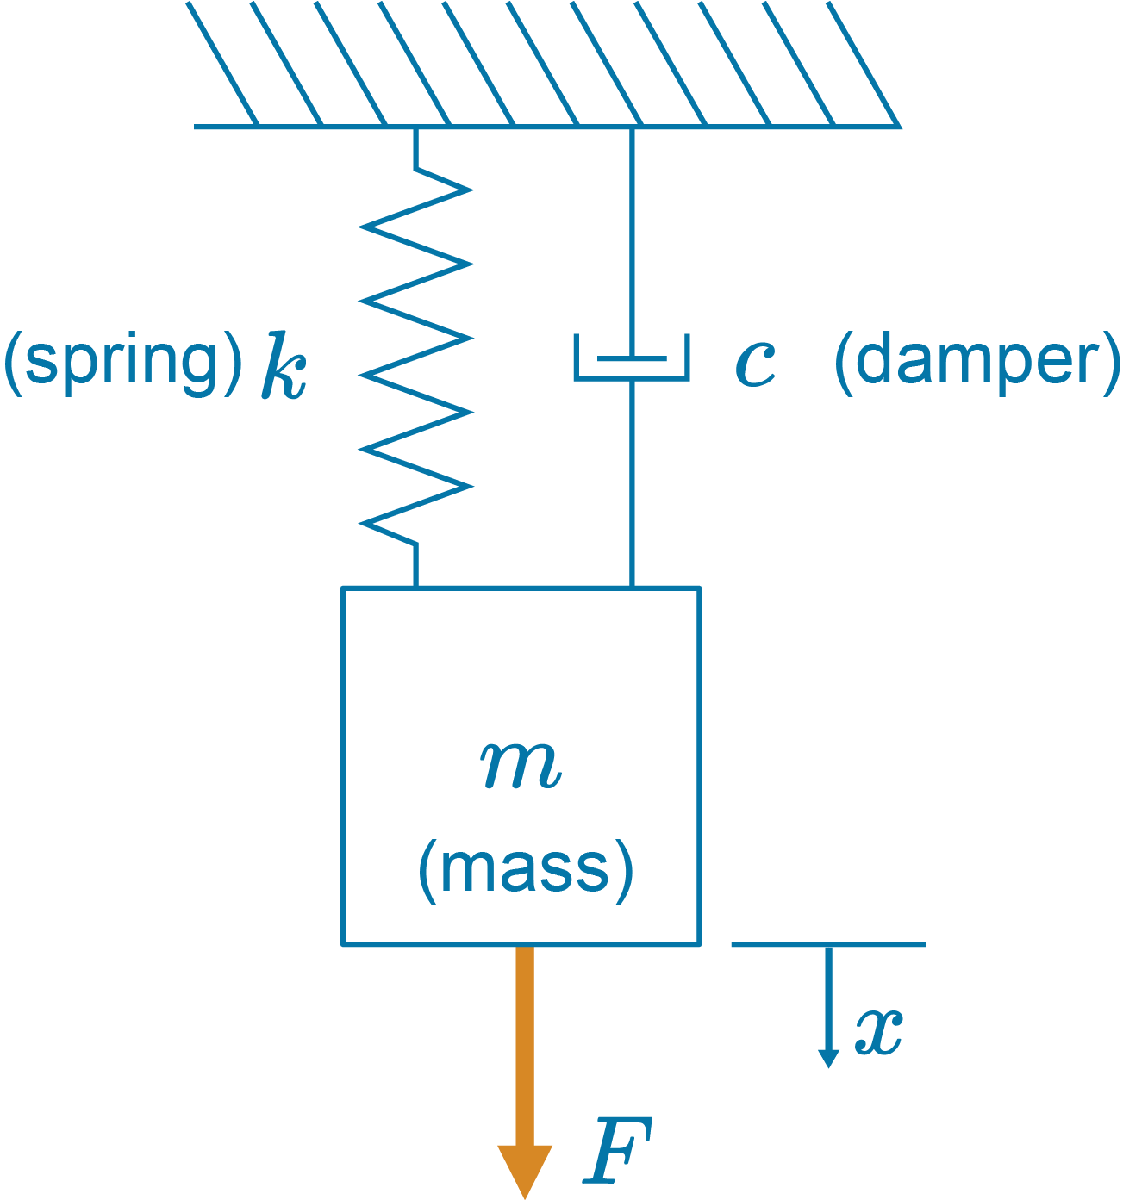

*Schematic of the mass-spring-damper system *

Several parameters determine the behavior of this mechanical system:

- $k$: spring stiffness [N/m]

- $c$: damping coefficient [N$\cdot$s/m]

- $m$: mass [kg]

- $F$: externally applied force [N] (can be constant or time-dependent: $F(t)$)

The time-dependent behavior of the system is solved for using the variables: 

- $t$: time since the start of the simulation [s]

- $x$: time-dependent ($x=x(t)$) displacement of the mass from the reference equilibrium position [m]

- $\dot{x}$: mass velocity [m/s]

- $\ddot{x}$: mass acceleration [m/s$^2$]

When a force is applied to the system, the mass will begin to vibrate. Over time, the vibration diminishes as mechanical energy is converted to heat by the dashpot.

 ** Try**

- On paper, draw a free body diagram of the forces acting on the mass $m$.

- After drawing the free body diagram, apply Newton's second law to derive the equation of motion:      

                $m\ddot{x} \;=\;\;\sum Forces$.

fig = uifigure;
delete(fig)

showSolutionFBD = true; % Click the checkbox to view the solution
if(showSolutionFBD)
    [I,~,~] = imread(fullfile("Images","mass_spring_damper_FBD.png"));
    imshow(I,InitialMagnification=50)
end

#### Modeling vehicle suspension as a mass-spring-damper

The mass-spring-damper is suitable for modeling a shock absorber as the components of the model correspond directly to the mechanical components. The model spring and damper represent the physical spring and shock, respectively. These two components serve complementary functions in bringing the vehicle smoothly back to equilibrium.

- The shock component dissipates mechanical energy, which is given off as heat. This reduces the overall motion of the vehicle after contacting a bump.

- The spring spreads the response to an impact out over time. The initial impact compresses the spring, followed by regular oscillations. These oscillations give time for the shock to dissipate mechanical energy.

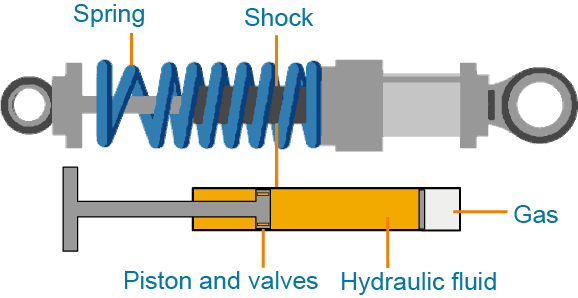

*Simplified schematic of a shock/spring system. Internally, the shock has a piston that moves through hydraulic fluid. The viscous resistance of the fluid dissipates mechanical energy as heat.*

In the simple idealization used in this script, the vehicle's entire suspension system (rather than a single shock absorber) is modeled as a single mass-spring-damper with stiffness, $k$, and damping coefficient, $c$. The mass, $m$, is the mass of the vehicle itself. Drive over a pothole and you've applied an impulse force, $F$.

 **Reflect**

- Try drawing a free body diagram for a vehicle with a suspension described by a single mass-spring-damper system that has driven over a speed bump.

- What major features are left out of the model by assuming a single mass-spring-damper system for the entire suspension?

## 2. Manipulate the mass-spring-damper equation using symbolic operations

The mass-spring-damper differential equation that you derived in the previous section is

    $m\ddot{x} + c \dot{x} + kx =  F$.

When solving an ordinary differential equation (ODE) in Simulink, it helps to have it in the form: $\ddot{x} = \ldots$. This form makes constructing the solution model simpler. Only two simple algebraic steps are required to solve for$\ddot{x}$ here. But, in more realistic model systems, there are typically several equations that need to be solved simultaneously, making the algebra tedious and error-prone. To prepare yourself for those problems, you can use symbolic computations to solve for $\ddot{x}$ in the mass-spring-damper ODE.

  **Pro-tip**: MATLAB symbolic variables and operations are not the same as regular MATLAB expressions. Visit [this documentation page](https://www.mathworks.com/help/symbolic/create-symbolic-numbers-variables-and-expressions.html) to learn a bit of the basic syntax for symbolic variables and expressions.

** Exercise. **In this exercise, you will define the equation in symbolic notation and then solve for $\ddot{x}$.

**Task 1.** Solve for $\ddot{x}$ on paper.

**Task 2**. Define seven symbolic variables in the space provided: x, x_dot, x_ddot, m, c, k, and F. You can define multiple symbolic variables in MATLAB using the command syntax: 

% Call the syms command here

checkSyms() % This checks if you defined the symbolic variables

**Task 3. **Write the mass-spring-damper equation in terms of symbolic variables and assign it to msdEq.

  **Pro-tip**: When you write a symbolic equation, you assign the whole equation to a MATLAB variable using $=$. This means that the equals sign in the symbolic equation must be written using `==`. For example: 

msdEq = NaN % Replace NaN with your equation
checkMSDeq(msdEq) % This helper function (located at the bottom of the script) checks your equation

**Task 4. **Solve for `x_ddot` in the mass-spring-damper equation using [`solve(equation, variable)`](https://www.mathworks.com/help/symbolic/solve.html) and assign the result to `sltnMSD`. In this syntax, `equation` is the symbolic equation to be solved and `variable` is the symbolic variable to be solved for.

sltnMSD = NaN % Replace NaN with a call to solve
checkMSDSolve(sltnMSD) % This helper function (located at the bottom of the script) checks your expression

 **Reflect:**

- Does the solution you found in Task 4 match the one you found by hand in Task 1?

## 3. Solve a first-order ODE in Simulink

To investigate the dynamics of the mass-spring-damper, you can solve for its solutions in Simulink. Before you solve the second-order mass-spring-damper ODE, you can solver a simpler first-order ODE. In Simulink, ODEs are solved using integrator blocks.

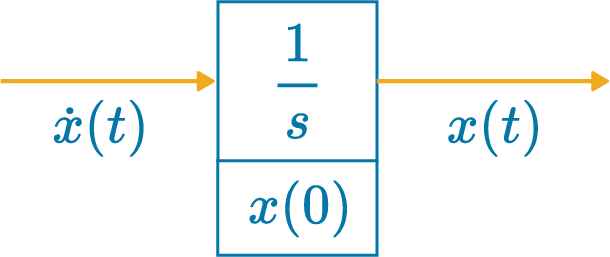

*Simplified schematic for solving a first-order ODE in Simulink. The integrator block (labeled *$1/s$*) integrates once, reducing the derivative order by one. The integrator block also provides the initial condition, *$x(0)$*.*

 **Did you know? **The integrator block is labeled $1/s$ because integration in the time domain is equivalent to division by $s$ in the Laplace domain.

** Exercise. **Consider the ODE:

    
$$\dot{x} = -x$$
 

    subject to $x(0) = 10$

(a) Solve for the analytic solution by hand. Type your solution below in terms of $t$.

syms t;
xSltn = NaN; % Replace NaN with your solution in terms of t. Use exp for the exponential.
checkFirstOrder(xSltn)

(b) [Create a new Simulink model](matlab: open_system(new_system('simpleODE'))) and build solution model shown below by performing the following:

- Add an **integrator** block and set the initial condition of the integrator block to $x(0) = 10$ (double-click the block to access the dialogue).

- Add a **gain** block with value -1.

- Add a **scope** block.

- Connect as shown.

- Run the model, and double click the scope to verify that the output matches the solution found in (a).

 **Pro-tip**: Double-click anywhere in the Simulink canvas and type the name of the block you want to add.

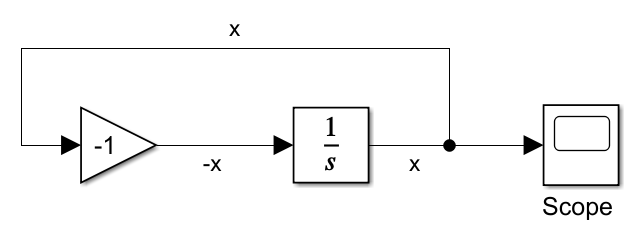

Simulink ODE solver for $\dot{x} = -x$.

 **Reflect:**

- What does the [gain block](https://www.mathworks.com/help/simulink/slref/gain.html) do?

- The input to the integrator is labeled $-x$. Why is $-x$ used as the input to the integrator block?

- The output of the integrator block loops back to the input. Why is this necessary?

Having difficulty creating your Simulink model? Check out [this blog post](https://blogs.mathworks.com/simulink/2008/05/23/how-to-draw-odes-in-simulink/) to learn more about solving ODEs in Simulink.

## 4. Solve the mass-spring-damper model in Simulink

In this section, you will solve the mass-spring-damper 2nd order ODE using Simulink.

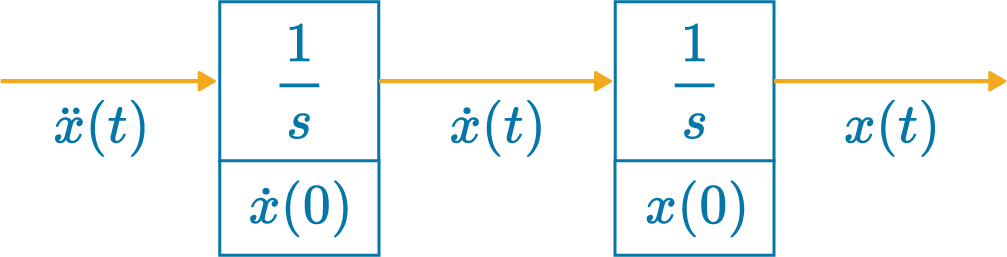

*Solving a second-order ODE in Simulink requires two integrator blocks.*

To provide the input to the first integrator block, you can use the expression for $\ddot{x}$:

    $\ddot{x} = \frac{ F - c \dot{x} - kx}{m}$.

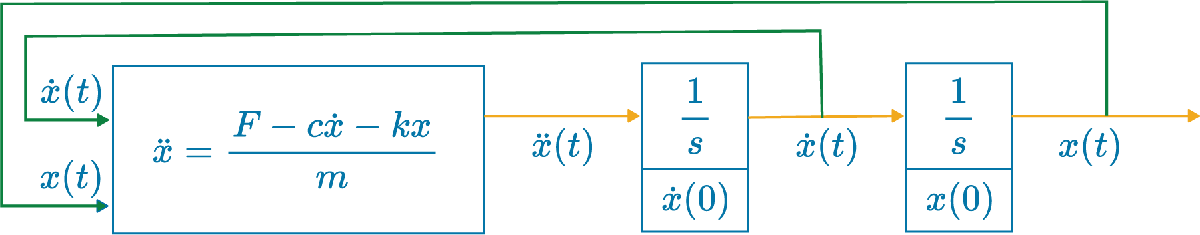

*The inputs (*$\dot{x}$ and $x$) *required to compute the expression for *$\ddot{x}$* are obtained from the outputs of the integrator blocks.*

Earlier, you solved for $\ddot{x}$ in the equations of motion using symbolic computations in MATLAB. You can port this expression directly into Simulink by writing it into a MATLAB Function block.

** Exercise. **Open the Simulink model [mfb.slx](matlab: open_system('models/mfb')) and complete the MATLAB Function block by adding the MATLAB expression for $\ddot{x}$.

yourExpression = char(sltnMSD) % This displays your expression for x_ddot.

- You can use the MATLAB expression that you symbolically computed above for `x_ddot` inside the MATLAB Function Block.

- Double-click the [MATLAB Function block](matlab: hilite_system('mfb/double-click me'); pause(1); hilite_system('mfb/double-click me','none');) to edit the MATLAB code inside.

- Run the model to check if your expression is correct.

** Exercise. **In this exercise, you will complete a model that solves the mass-spring-damper ODE in Simulink.

To compute the solution to this second-order ODE, two integrator blocks are required. 

- Open [msd.slx](matlab: open_system('models/msd')).

- Add two **Integrator** blocks to complete the system and connect them to the system.

- Set the initial conditions of the Integrator blocks to $\dot{x}(0) = -3$ and $x(0)=2$.

- Run the model and double-click the [Scope](matlab: hilite_system('msd/Scope'); pause(1); hilite_system('msd/Scope','none');) to view the output. If it matches the solution shown below, your model is correct.

            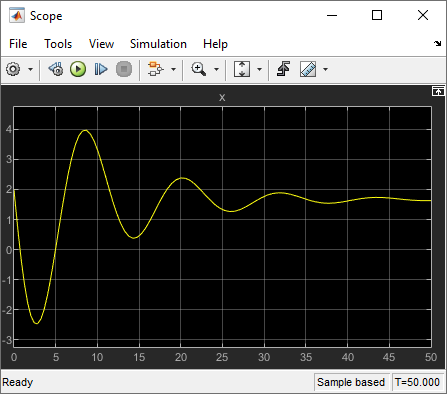

*            Solution to the mass-spring-damper system*

Having trouble? Check out the completed model: [msdSoln.slx](matlab: open_system('models/msdSoln')).

**Visualize the motion of the mass-spring-damper**

With the model complete, you can visualize the motion. The  `sim` command simulates a completed mass-spring-damper model, `msdSimulationOutput.slx`. The local function `animateMSD` creates an animation of the output from the model.

n = 150; % The number of steps used in the visualization
visualize = true; % Click the checkbox to show the visualization
if(visualize)
    simOut = sim("msdSimulationOutput"); % Run the Simulink model
    animateMSD(simOut.tout,simOut.yout,0.5,n)
end

 ** Try**

Open the Simulink model [msdSimulationOutput.slx](matlab: open_system("models/msdSimulationOutput")) and then try the following.

- Set the damping to 0. Then, rerun this section of the script. How is the behavior affected?

- Lower the spring stiffness in the model and then rerun the animation here.

- Adjust the initial conditions in the model. First, change the initial position $x(0)$, then change the initial velocity $\dot{x}(0)$. Do these have different or similar effects?

## 5. Tune suspension damping using the mass-spring-damper model

Now that you've solved the ODE in Simulink, you can apply it to tune the suspension of a vehicle modeled as a single mass-spring-damper. 

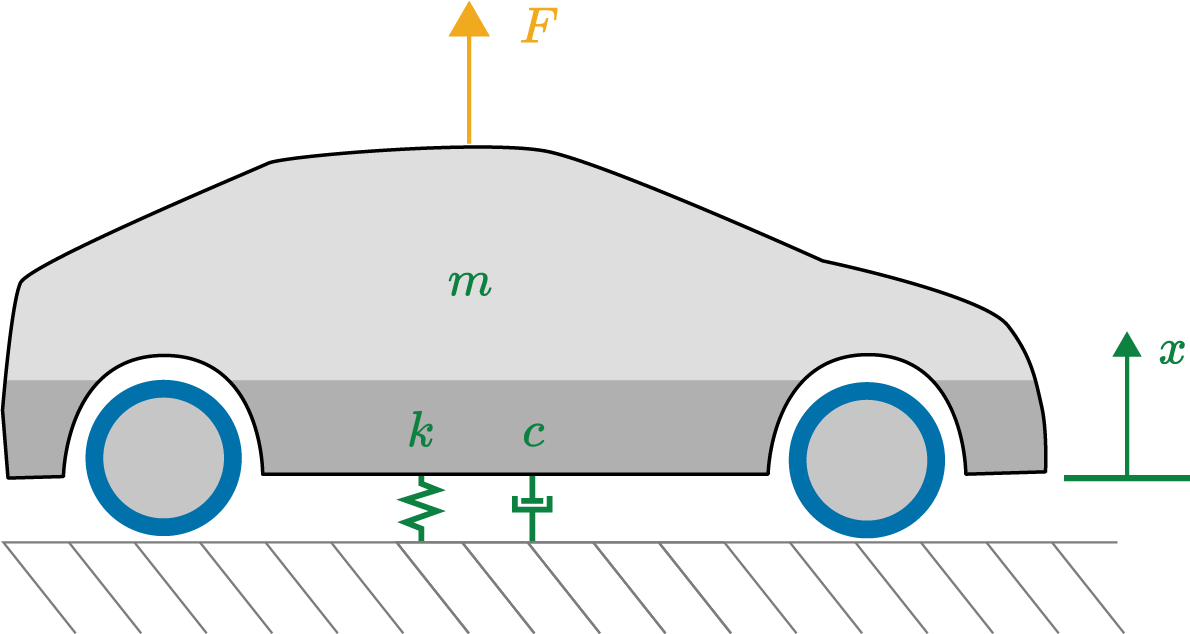

*Schematic of the mass-spring-damper model applied to a vehicle. The entire suspension has a stiffness, *$k$*, and damping, *$c$*. At rest, the vertical position of the vehicle's undercarriage is *$x=0$. 

Your goal in this section is to tune the suspension so that it meets design requirements. 

** Exercise. **Consider a vehicle with the following properties:

- Vehicle mass: 1360 kg

- Suspension stiffness: 26,000 N/m

Your task is to select a damping, $c$, that meets the following design requirements. After encountering a bump in the road, which is modeled by a 9000 N force applied for 0.1 seconds, the vehicle should:

- have a maximum absolute vertical displacement of less than 0.1 m after impact,

- after 1 second, the absolute vertical displacement should be less than 0.02 m, and

- the damping coefficient should be as small as possible while still meeting requirements 1 and 2.

Assume that, initially, the vehicle has no motion or displacement in the vertical direction.

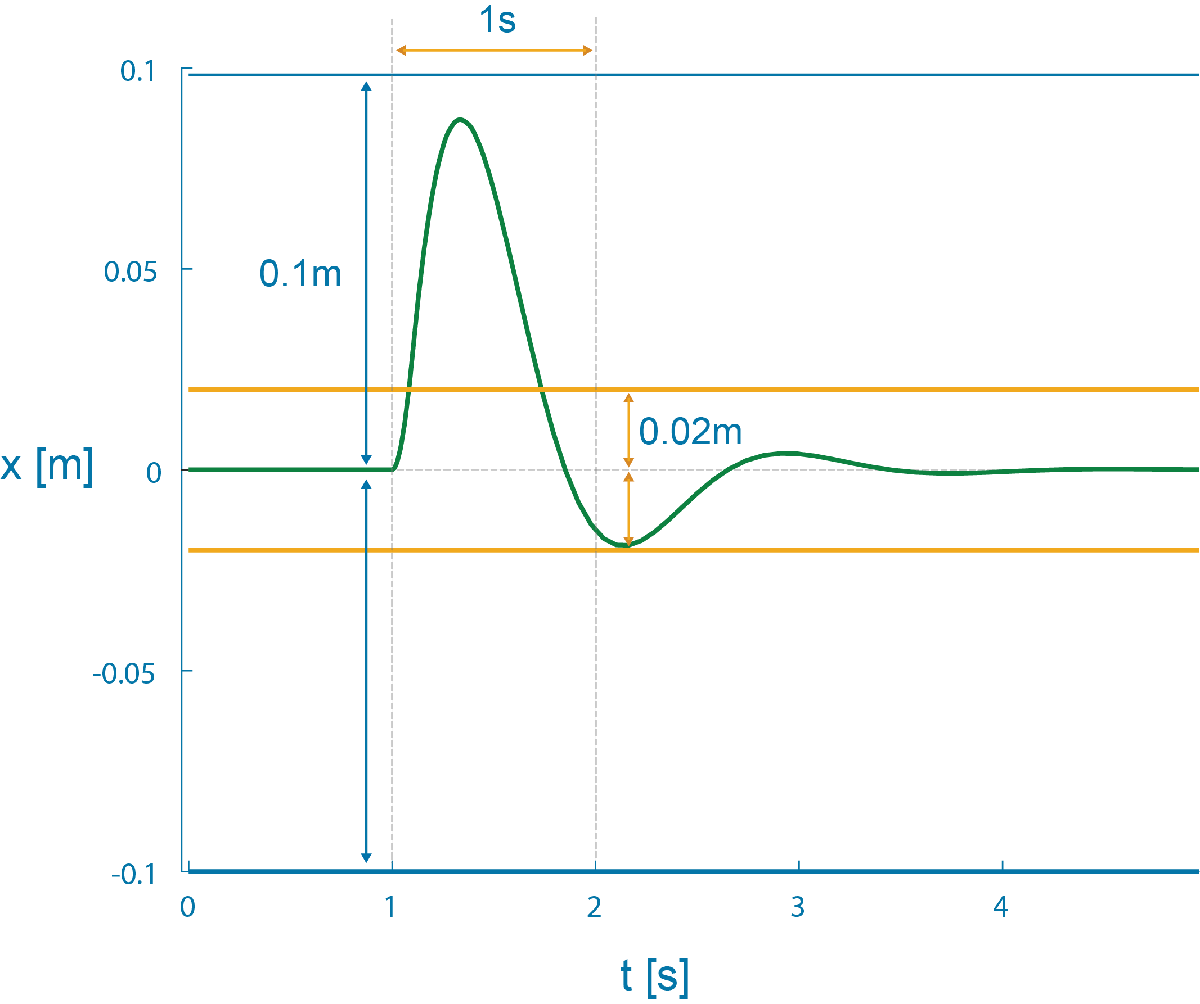

*Schematic of the design requirements. The initial vertical displacement should be less than 0.1 m. Subsequent oscillations should have a magnitude of less than 0.02 m.*

 ** Tasks. **To adjust the design so that it meets the requirements, perform the following.

- Open the model [msdTune.slx](matlab: open_system('models/msdTune')). This model has a masked subsystem containing the mass-spring-damper model you worked with in the previous section. You can look under the mask by clicking the arrow ( ) to view this model. 

- Double-click the [mask](matlab: hilite_system('msdTune/mass-spring-damper model'); pause(1); hilite_system('msdTune/mass-spring-damper model','none');) of the model and set the initial conditions of the displacement $x(0)$ and velocity $\dot{x}(0)$.

- Set the fixed parameters of the model: [*k*](matlab: hilite_system('msdTune/k'); pause(1); hilite_system('msdTune/k','none');) and [*m*](matlab: hilite_system('msdTune/m'); pause(1); hilite_system('msdTune/m','none');). The model already applies the correct impulse force $F$, so do not modify the "F" subsystem.

- Set a damping coefficient, [*c*](matlab: hilite_system('msdTune/c'); pause(1); hilite_system('msdTune/c','none');), and run the model. View the vehicle's bouncing behavior in the [scope](matlab: hilite_system('msdTune/Scope'); pause(1); hilite_system('msdTune/Scope','none');).

- Tune the damping until all three requirements have been met.

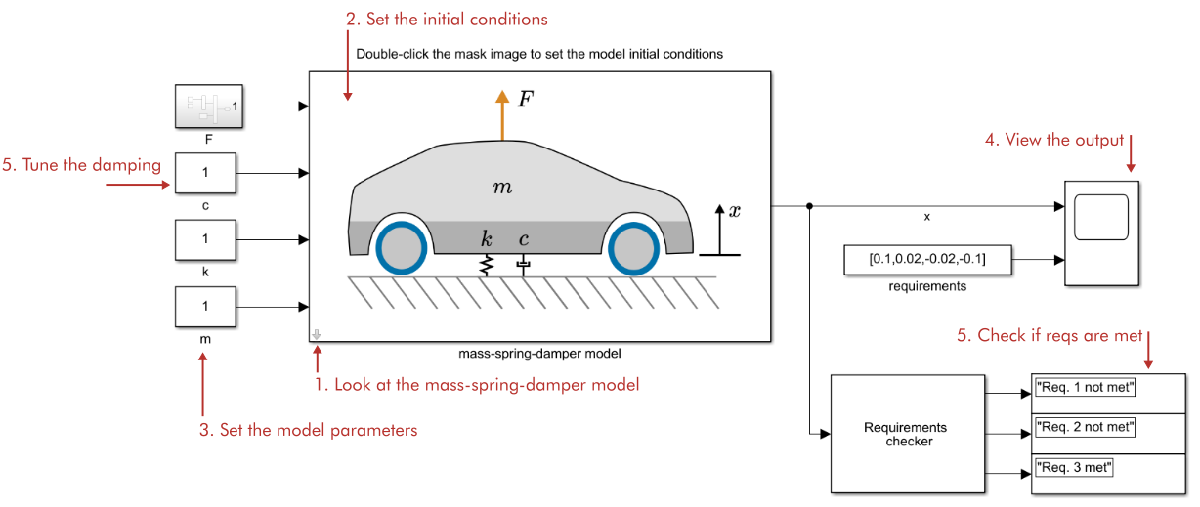

*Schematic of the Simulink model and where you should perform the tasks*

### 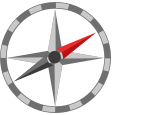**Further exploration**

In reality, a vehicle's suspension system is more complicated than a single mass-spring-damper. An uncomplicated improvement to this model uses two mass-spring-dampers: one for the front suspension and one for the rear. To learn more about this approach, you can review the [automotive suspension](https://www.mathworks.com/help/simulink/slref/automotive-suspension.html) application in the Simulink documentation.

**Helper functions**

These functions check answers and generate animations.

function checkSyms
    varList = ["x","x_dot","x_ddot","m","c","k","F"];
    for k = 1:length(varList)
       varExists = evalin("caller",strcat("exist('",varList(k),"','var')"));
       if(varExists)
           varSym = evalin("caller",strcat("isequal(class(",varList(k),"),""sym"")"));
           if(varSym)
              disp(strcat("Success! ",varList(k)," is symbolic."))
           else
              warning(strcat(varList(k)," exists but is not symbolic.")) 
           end
       else
         warning(strcat(varList(k)," does not exist!"))
       end
    end
end

function correct = isEqualCheck(userSubmission,correctAnswer)
    correct = true;
    if( isequal(userSubmission,correctAnswer) )
        disp("Correct!")
    else
        warning("Your answer does not match the expected result.")
        correct = false;
    end
end

function checkMSDeq(msdEqUser)
    syms x x_dot x_ddot m c k F
    msdEq = m*x_ddot + c*x_dot + k*x == F;
    isEqualCheck(solve(msdEqUser,x_ddot), solve(msdEq,x_ddot));
end

function checkMSDSolve(sltnUser)
    syms x x_dot x_ddot m c k F
    msdEq = m*x_ddot + c*x_dot + k*x == F;
    sltn = solve(msdEq,x_ddot);
    isEqualCheck(sltnUser,sltn);
    end

function checkFirstOrder(xSltnUser)
    syms t;
    xSltn = 10*exp(-t);
    correct = isEqualCheck(xSltnUser,xSltn);
    if(correct)
        tvec = linspace(0,10,500);
        figure("position",[1 1 400 200])
        plot(tvec,10*exp(-tvec))
        xlabel("$t$","Interpreter","latex")
        ylabel("$x(t)$","Interpreter","latex")
        title("Solution curve")
    end
end

function animateMSD(tin,xin,spacingMultiplier,steps)
    
    Nmass = size(xin,2); % Number of masses

    % Options that determine how the graph will look
    colors = lines(Nmass); 
    w = 1; % Mass width
    h = 2; % Height of masses
    y = 0; % Vertical position
    
    % Local variables
    t = linspace(tin(1),tin(end),steps);
    x = zeros(steps,Nmass);
    for k = 1:Nmass
        x(:,k) = interp1(tin,xin(:,k),t);
    end
    spacing = 2*max(abs(x),[],"all")*spacingMultiplier;
    xmax = spacing*2.5 + 2;
    
    % Loop to create the animation
    figure;    
    for j = 1:numel(t)
       
        subplot(2,1,1) % This shows the masses
        cla
        hold on
        x0k = 0;
        for k = 1:Nmass
            % Plot springs
            xc = spacing*k+x(j,k)-w/2;       
            xs = linspace(x0k,xc,12);
            ys = 0.25*(-1).^(1:numel(xs));
            plot(xs,ys + 0.5,SeriesIndex="none");
            % Plot dampers
            yd = 1.65;
            xd = x0k + (xc-x0k)*0.5+0.1;
            xd2 = x0k + (xc-x0k)*0.5;
            xd3 = x0k + (xc-x0k)*0.5 + 0.2;
            plot([x0k,xd,NaN,xd,xd],[yd,yd,NaN,yd-0.1,yd+0.1],SeriesIndex="none")
            plot([xd2,xd3,NaN,xd2,xd3,NaN,xd3,xd3,NaN,xd3,xc],[yd-0.15,yd-0.15,NaN,yd+0.15,yd+0.15,NaN,yd-0.15,yd+0.15,NaN,yd,yd],SeriesIndex="none")
            % Update position
            x0k = xc + w;
            % Plot masses
            x1 = spacing*k + x(j,k) - 0.5;
            rectangle("Position",[x1 y w h],"FaceColor",colors(k,:))
            text(x1 + w/2, h/2,"m_" + num2str(k),"HorizontalAlignment","center","color","w")
            % Plot x1, x2 distances
            quiver(spacing*k, y+h*1.1, x(j,k),0,"-","MaxHeadSize",1/(x(j,k))^2,SeriesIndex="none")
            plot([1;1]*[spacing*k, spacing*k+x(j,k)],[0.95;1.05]*(y*[1,1]+h*1.1),"-","markersize",12,SeriesIndex="none")
            text((spacing*k + spacing*k+x(j,k) )/2,(y+h*1.3),"x_"+num2str(k),"HorizontalAlignment","Center")
        end
        hold off
        axis([0,xmax,-1,3])
        set(gca,"ytick",[])
        xlabel("reference axis [m]")
    
        subplot(2,1,2) % This shows the position plots with moving markers
        cla
        hold on
        plot(t,x)
        for k = 1:Nmass
            plot(t(j),x(j,k),"o","MarkerFaceColor",colors(k,:),SeriesIndex="none")
        end 
        xlabel("t [s]")
        ylabel("x [m]")
        hold off
        box off
        drawnow
    end
end
